# Aerosol Jet Extraction

clc;    % Clear the command window.
close all;  % Close all figures (except those of imtool.)
clear;  % Erase all existing variables. Or clearvars if you want.
workspace;  % Make sure the workspace panel is showing.
format long g;
format compact;

folder = 'C:\Users\Lavision\Desktop\full_length\5x5 gaussian smoothing';
baseFileName = 'testing10001.png';
% Get the full filename, with path prepended.
fullFileName = fullfile(folder, baseFileName);
% Check if file exists.
if ~exist(fullFileName, 'file')
  % File doesn't exist -- didn't find it there.  Check the search path for it.
  fullFileName = baseFileName; % No path this time.
  if ~exist(fullFileName, 'file')
    % Still didn't find it.  Alert user.
    errorMessage = sprintf('Error: %s does not exist in the search path folders.', fullFileName);
    uiwait(warndlg(errorMessage));
    return;
  end
end

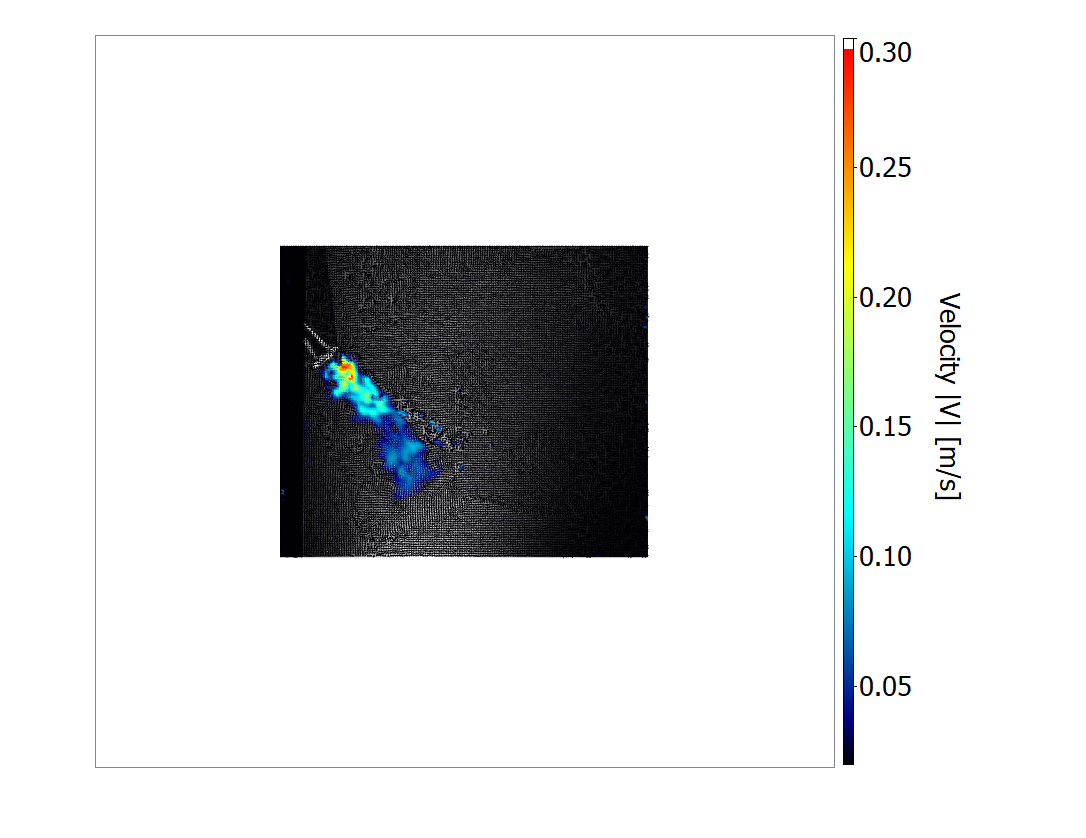

rgbImage = imread(fullFileName);
imshow(rgbImage)

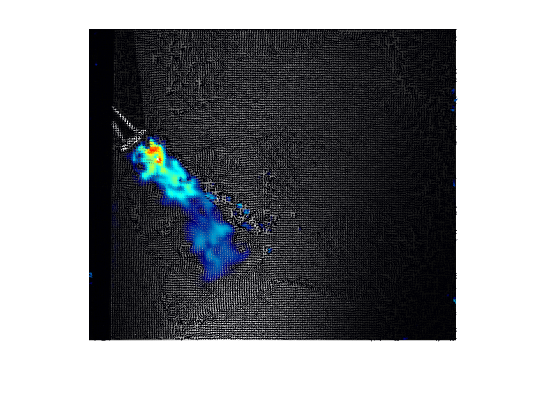

% Crop image
targetSize = [193 218 368 312];
crop_rgbImage = imcrop(rgbImage,targetSize);
imshow(crop_rgbImage)

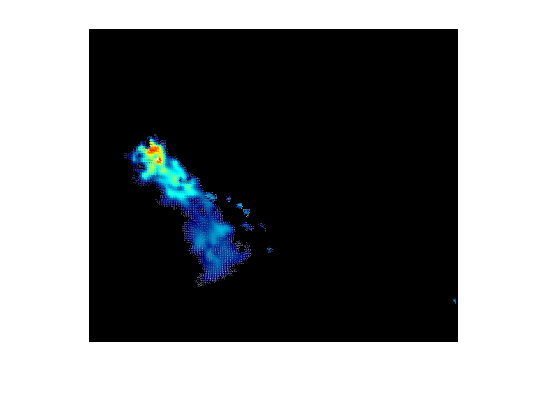

[mask, maskedRGBImage] = createMask(crop_rgbImage); 
mask = imfill(mask,8,'holes');
mask = bwareafilt(mask, 8); 
maskedRgbImage = bsxfun(@times, crop_rgbImage, cast(mask,class(crop_rgbImage)));
imshow(maskedRgbImage);

imshow(maskedRGBImage);

imshow(mask);

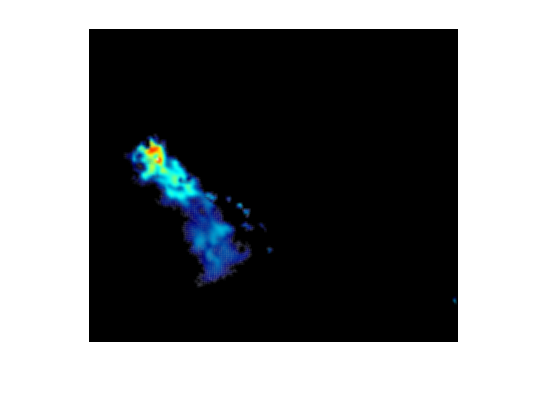

redChannel = maskedRgbImage(:, :, 1);
greenChannel = maskedRgbImage(:, :, 2);
blueChannel = maskedRgbImage(:, :, 3);
windowSize = 3;
kernel = ones(windowSize) / windowSize ^ 2;
% Blur the individual color channels.
smoothedPictureR = conv2(double(redChannel), kernel, 'same');
smoothedPictureG = conv2(double(greenChannel), kernel, 'same');
smoothedPictureB = conv2(double(blueChannel), kernel, 'same');
% Recombine separate color channels into a single, true color RGB image.
smoothrgbImage = uint8(cat(3, smoothedPictureR , smoothedPictureG, smoothedPictureB));
imshow(smoothrgbImage);

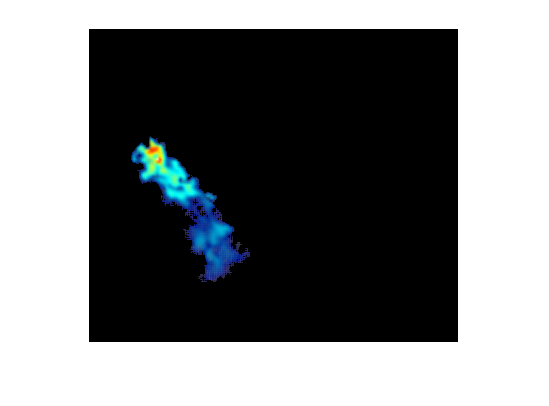

im = im2double(smoothrgbImage);
im_mask = rgb2gray(im) > .14;
rgs = bwconncomp(im_mask);
[max_area, idx] = max(cellfun(@(x) numel(x), rgs.PixelIdxList));
mask = zeros(size(im_mask));
mask(rgs.PixelIdxList{idx}) = 1;
im(~mask(:,:,[1 1 1])==1) = 0;
imshow(im)

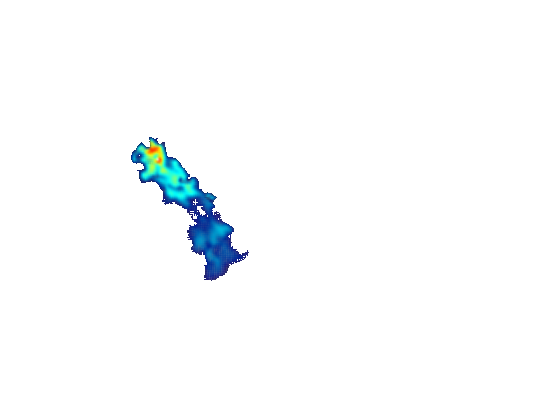

intensity_filter = .39;
I2 = im;
A = I2;
[row, col, xx] = size(A);
for i = 1:row;
    for j = 1:col;
        if(A(i,j,:) < intensity_filter);
            A(i,j,:) = 1;% 0 or 255
        end
    end
end
figure,imshow(A);

Iteration count = 1, obj. fcn = 5194.046270
Iteration count = 2, obj. fcn = 4985.634848
Iteration count = 3, obj. fcn = 3841.405363
Iteration count = 4, obj. fcn = 593.341804
Iteration count = 5, obj. fcn = 464.093095
Iteration count = 6, obj. fcn = 381.068093
Iteration count = 7, obj. fcn = 252.693105
Iteration count = 8, obj. fcn = 193.379913
Iteration count = 9, obj. fcn = 178.759906
Iteration count = 10, obj. fcn = 175.187501
Iteration count = 11, obj. fcn = 174.275472
Iteration count = 12, obj. fcn = 174.028405
Iteration count = 13, obj. fcn = 173.958375
Iteration count = 14, obj. fcn = 173.938019
Iteration count = 15, obj. fcn = 173.932022
Iteration count = 16, obj. fcn = 173.930243
Iteration count = 17, obj. fcn = 173.929713
Iteration count = 18, obj. fcn = 173.929554
Iteration count = 19, obj. fcn = 173.929507
Iteration count = 20, obj. fcn = 173.929493
Iteration count = 21, obj. fcn = 173.929489


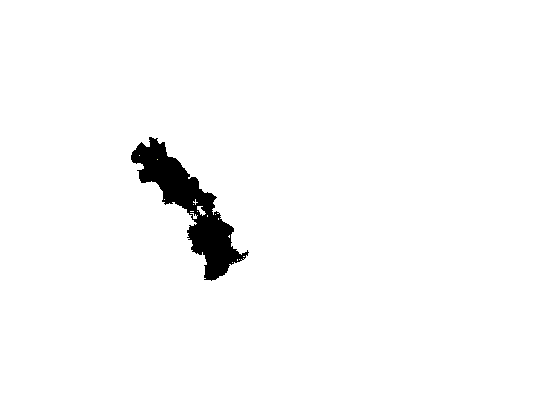

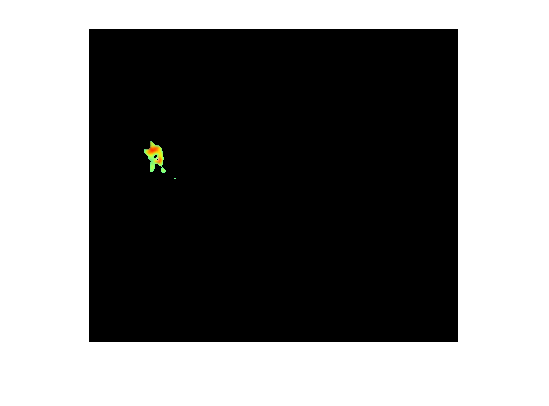

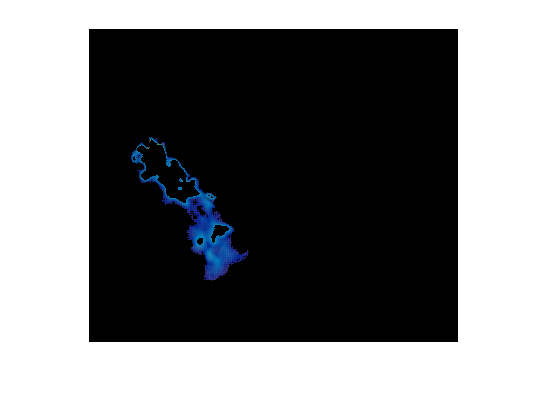

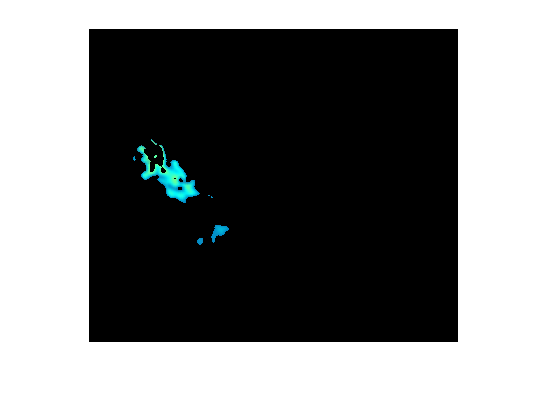

(:,:,1) =
  Columns 1 through 19
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
  Columns 20 through 38
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
  Columns 39 through 57
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
  Columns 58 through 76
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
  Columns 77 through 95
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
  Columns 96 through 114
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
  Columns 115 through 133
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
  Columns 134 t

A =im2double(A);
%disp(A);
k = 4;
imgCluster(A, k);

function [BW,maskedRGBImage] = createMask(RGB)

I = rgb2hsv(RGB);

channel1Min = 0.972;
channel1Max = 0.711;

channel2Min = 0.087;
channel2Max = 1.000;

channel3Min = 0.179;
channel3Max = 1.000;

sliderBW = ( (I(:,:,1) >= channel1Min) | (I(:,:,1) <= channel1Max) ) & ...
	(I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
	(I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
BW = sliderBW;
maskedRGBImage = RGB;

maskedRGBImage(repmat(~BW,[1 1 3])) = 0;

end